%{
Author: Milind Kumar V

This file contains code to simulate Jakes' model for Rayleigh fading. This
code is being written for the first programming assignment of the course
EE5141 at IIT Madras.
%}

% setting the random number generator
rng(1234);

% setting waveform sampling rate as defined in the problem
global sampRate
sampRate = 1000;


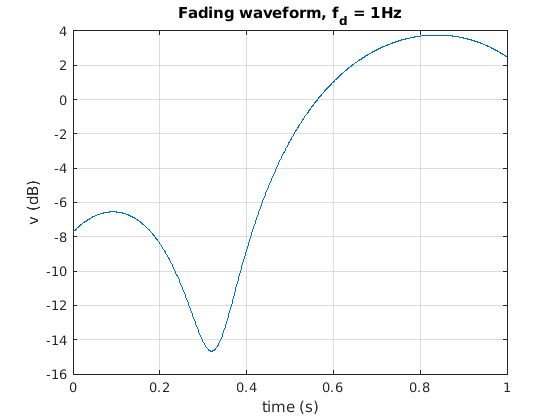

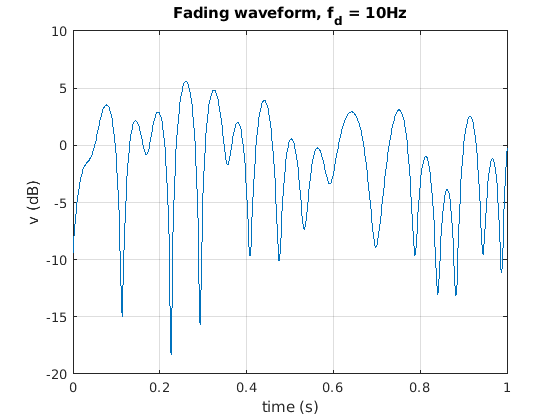

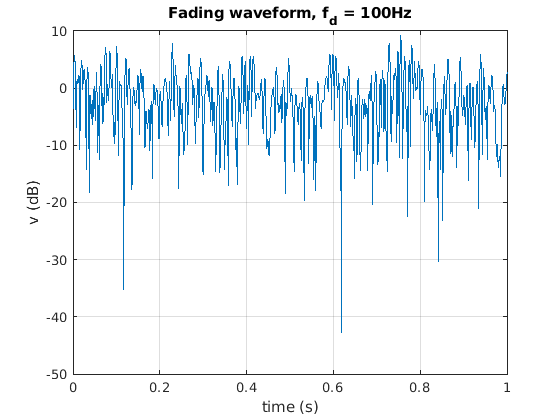

% Question 1a: Simulate Rayleigh fading using Jakes' model for different
% values of fd. Set M = 20 and duration = 1s.

fdArray = [1, 10, 100];
M = 20;
duration = 1;
time = linspace(0, duration, duration*sampRate);

for i = 1:length(fdArray)
    fdValue = fdArray(i);
    waveform = JakesModel(M, fdValue, duration);
    envelope = 20*log10(abs(waveform));
    % Plotting the envelope
    figure
    plot(time, envelope)
    grid on
    titleText = "Fading waveform, f_d = " + fdValue + "Hz"; 
    title(titleText)
    xlabel("time (s)")
    ylabel("v (dB)")
    
    
end

%{
zRealArray = zReal(M, fd, duration)

Inputs 
    M (int): M+1 oscillators are used in the system
    fd (float): maximum doppler frequency 
    duration (float): duration of the fading waveform in seconds
Outputs
    zRealArray (array): an array of the real parts of the (float) 
        fading waveform values of size number_of_samples x 1
%}

function zRealArray = zReal(M,fd,duration)
    N = 4*M + 2;
    global sampRate
    nSamples = duration*sampRate;
    timeArray = linspace(0, duration, nSamples)'; % time array needs to be a column vector
    
    % generating variables for vectorized code
    n = 1:M;
    betaArray = pi*n/(M + 1);
    fnArray = fd*cos(2*pi*n/N);
    phinArray = -pi + (pi - (-pi)).*rand(1,M);
    phi0 = -pi + (pi - (-pi)).*rand;
    fnMatrix = repmat(fnArray, nSamples, 1);
    
    % Generating zR
    scale = 2/(sqrt(N));
    cosTerm1 = cos(betaArray);
    cosTerm2 = cos(2*pi*(fnMatrix.*timeArray) + phinArray);
    term1Matrix = cosTerm1.*cosTerm2; 
    term1 = 2*sum(term1Matrix,2);
    term2 = sqrt(2)*cos(2*pi*fd*timeArray + phi0);
    
    zRealArray = scale*(term1 + term2);
        
end


%{
zImagArray = zImag(M, fd, duration)

Inputs 
    M (int): M+1 oscillators are used in the system
    fd (float): maximum doppler frequency 
    duration (float): duration of the fading waveform in seconds
Outputs
    zImagArray (array): an array of the imaginary parts of the (float) 
        fading waveform values of size number_of_samples x 1
%}

function zImagArray = zImag(M,fd,duration)
    N = 4*M + 2;
    global sampRate
    nSamples = duration*sampRate;
    timeArray = linspace(0, duration, nSamples)'; % time array needs to be a column vector
    
    % generating variables for vectorized code
    n = 1:M;
    betaArray = pi*n/(M + 1);
    fnArray = fd*cos(2*pi*n/N);
    phinArray = -pi + (pi - (-pi)).*rand(1,M);
    fnMatrix = repmat(fnArray, nSamples, 1);
    
    % Generating zR
    scale = 2/(sqrt(N));
    sinTerm1 = sin(betaArray);
    cosTerm2 = cos(2*pi*(fnMatrix.*timeArray) + phinArray);
    term1Matrix = sinTerm1.*cosTerm2; 
    term1 = 2*sum(term1Matrix,2);
    
    zImagArray = scale*(term1);

end

%{
zSequence = JakesModel(M, fd, duration)

Inputs 
    M (int): M+1 oscillators are used in the system
    fd (float): maximum doppler frequency 
    duration (float): duration of the fading waveform in seconds
Outputs
    zSequence (array): an array of the of the (float) 
        fading waveform values of size number_of_samples x 1
%}

function zSequence = JakesModel(M, fd, duration)
    zSeq = zReal(M,fd,duration) + 1j*(zImag(M, fd, duration));
    zSeqPower = mean(abs(zSeq).^2); % FIXME: square or not?
    scale = 1/sqrt(zSeqPower); % FIXME: remove sqrt?
    zSequence = scale*zSeq;
end